# Excercises

% 37.3, 37.4
[centerOfMass, centerOfBuoyancy, P] = calculate_boat(250, @(P) P(2, :) >= ((2 / 1 * P(1, :)) .^ 8) & P(2, :) <= 0.5)

centerOfMass =     0.0000
    0.2648


centerOfBuoyancy =    -0.0000
    0.2648


P =    -0.4575   -0.4575   -0.4575   -0.4575   -0.4575   -0.4575   -0.4575   -0.4575   -0.4575   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4555   -0.4535   -0.4535   -0.4535   -0.4535   -0.4535   -0.4535   -0.4535   -0.4535   -0.4535   -0.4535   -0.4535   -0.4535   -0.4535   -0.4535   -0.4535
    0.4915    0.4925    0.4935    0.4945    0.4955    0.4965    0.4975    0.4985    0.4995    0.4745    0.4755    0.4765    0.4775    0.4785    0.4795    0.4805    0.4815    0.4825    0.4835    0.4845    0.4855    0.4865    0.4875    0.4885    0.4895    0.4905    0.4915    0.4925    0.4935    0.4945    0.4955    0.4965    0.4975    0.4985    0.4995    0.4585    0.4595    0.4605    0.4615    0.4625    0.4635    0.4645    0.4655    0.4665    0.4675    0.4685    0.4695    0.4705    0.4715    0

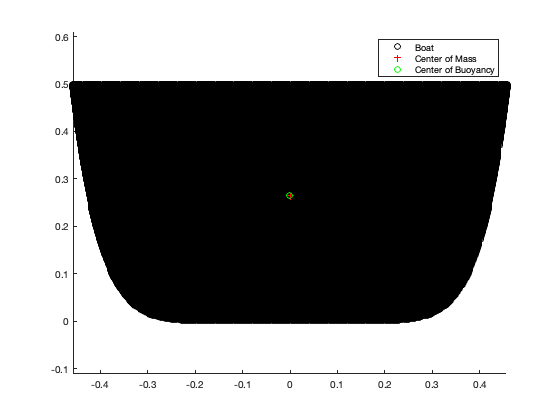

clf; scatter(P(1, :), P(2, :), 'k'); axis equal; hold on;
plot(centerOfMass(1), centerOfMass(2), "r+");
plot(centerOfBuoyancy(1), centerOfBuoyancy(2), "go");
legend("Boat", "Center of Mass", "Center of Buoyancy")  

## 37.5

com_rot = rotation_matrix(45) * centerOfMass,

com_rot =    -0.1873
    0.1873


cob_rot = rotation_matrix(45) * centerOfBuoyancy

cob_rot =    -0.1873
    0.1873


P_rot = rotation_matrix(45) * P

P_rot =    -0.6710   -0.6717   -0.6724   -0.6731   -0.6738   -0.6745   -0.6753   -0.6760   -0.6767   -0.6576   -0.6583   -0.6590   -0.6597   -0.6604   -0.6611   -0.6618   -0.6625   -0.6632   -0.6639   -0.6646   -0.6653   -0.6661   -0.6668   -0.6675   -0.6682   -0.6689   -0.6696   -0.6703   -0.6710   -0.6717   -0.6724   -0.6731   -0.6738   -0.6745   -0.6753   -0.6448   -0.6455   -0.6462   -0.6469   -0.6477   -0.6484   -0.6491   -0.6498   -0.6505   -0.6512   -0.6519   -0.6526   -0.6533   -0.6540   -0.6547
    0.0241    0.0248    0.0255    0.0262    0.0269    0.0276    0.0283    0.0290    0.0297    0.0134    0.0142    0.0149    0.0156    0.0163    0.0170    0.0177    0.0184    0.0191    0.0198    0.0205    0.0212    0.0219    0.0227    0.0234    0.0241    0.0248    0.0255    0.0262    0.0269    0.0276    0.0283    0.0290    0.0297    0.0304    0.0311    0.0035    0.0042    0.0050    0.0057    0.0064    0.0071    0.0078    0.0085    0.0092    0.0099    0.0106    0.0113    0.0120    0.0127 

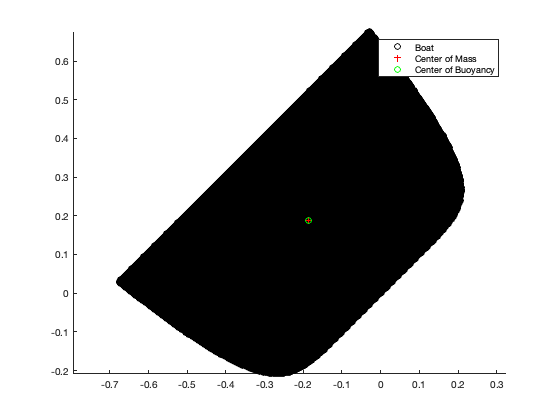

clf; scatter(P_rot(1, :), P_rot(2, :), "k"); axis equal; hold on;
plot(com_rot(1), com_rot(2), "r+");
plot(cob_rot(1), cob_rot(2), "go");
legend("Boat", "Center of Mass", "Center of Buoyancy")  

## Functions

function [centerOfMass, centerOfBuoyancy, pointsInBoat] = calculate_boat(density, predicate)
    xPoints = linspace(-1, 1, 1000);
    zPoints = linspace(0, 1, 1000);
    
    % I couldn't figure out that I needed to do this without the solutions
    areaPerCell = (xPoints(2) - xPoints(1)) * (zPoints(2) - zPoints(1)); % area represented by each point
    
    [X, Z] = meshgrid(xPoints, zPoints);
    P = [X(:)'; Z(:)'];
    
    isInsideBoat = predicate(P);
    pointsInBoat = P(:, isInsideBoat);
    massScalar = (isInsideBoat * density * areaPerCell);
    centerOfMass = (P * massScalar') / sum(massScalar, 2);
    areaScalar = isInsideBoat * areaPerCell;
    centerOfBuoyancy = (P * areaScalar') / sum(areaScalar);
end

function mat = rotation_matrix(angle)
    mat = [cosd(angle), -sind(angle); sind(angle), cosd(angle)];
end